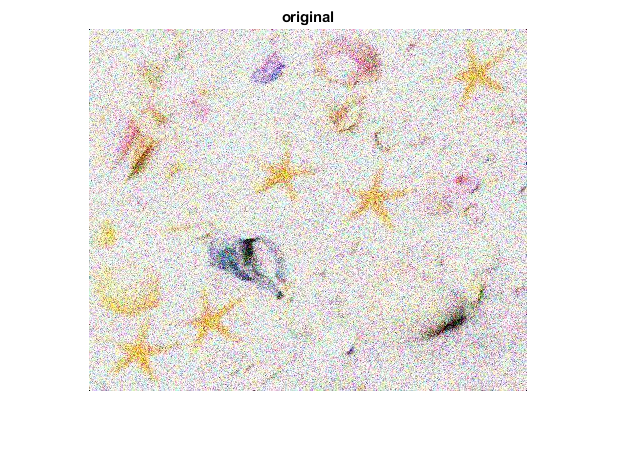

clear
% % %

im = imread("images\starfish_noise2.jpg");
imshow(im);
title("original");

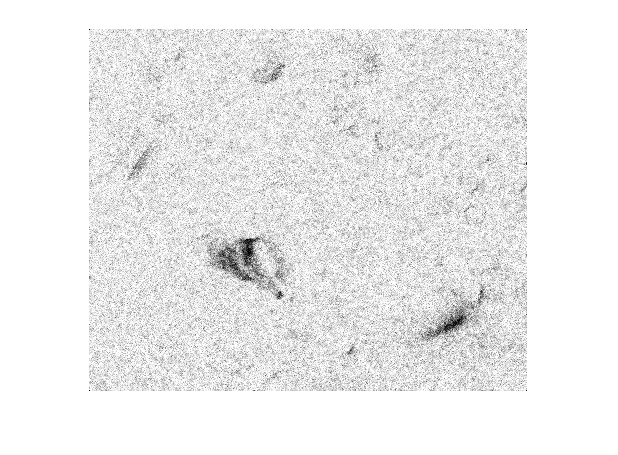

oim = im;
[c1,c2,c3] = imsplit(im);

imshow(c1)

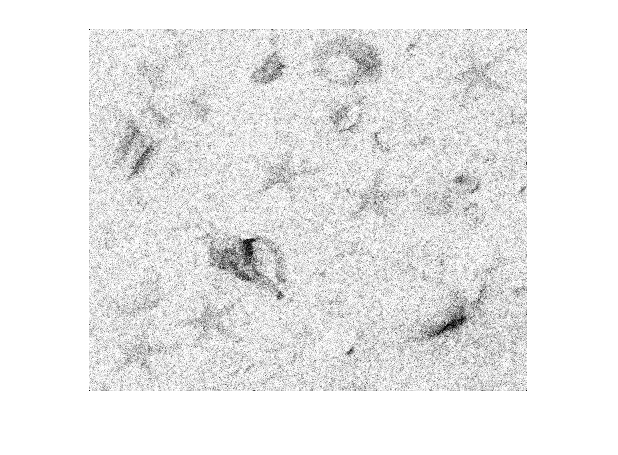

imshow(c2)

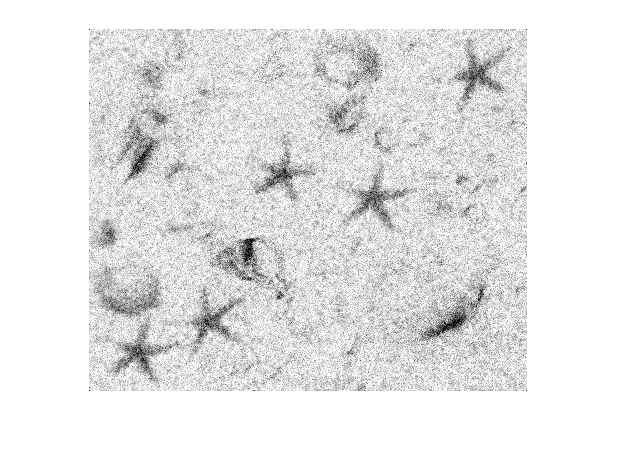

imshow(c3)

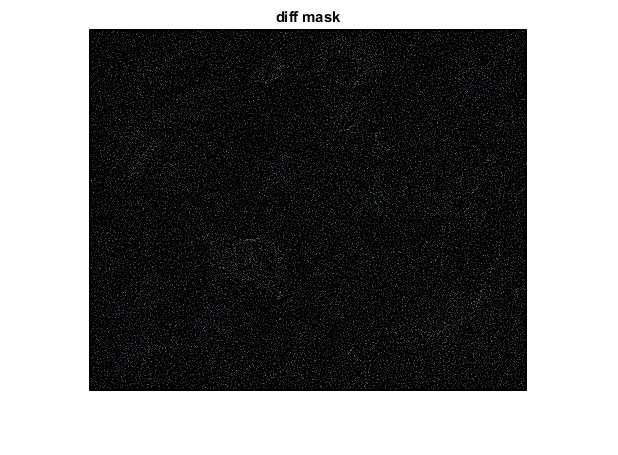


w = [0 1 0; 1 -4 1; 0 1 0];
c = 2;
r = 4;
n = 0;

% Create a filtered version of the input image.
filtered = oim;
[f1,f2,f3] = imsplit(filtered);
% f1 = medfilt2(f1);
% f2 = medfilt2(f2);
% f3 = medfilt2(f3);
f1 = imfilter(f1, ones(5)/25, 'same');
f2 = imfilter(f2, ones(5)/25, 'same');
f3 = imfilter(f3, ones(5)/25, 'same');
filtered = cat(3, f1, f2, f3);

% Calculate difference between the original and filtered images.
diffMask = filtered - oim;
imshow(diffMask);
title("diff mask");


% Get isolated 'noise' based on pixel diff. between original and filtered.
% If pixel diff is > noiseThresh, consider it to be noise.
noiseThresh = 30;
[n1b,n2b,n3b] = imsplit(diffMask); % Diff mask.
[n1,n2,n3] = imsplit(diffMask); % Diff mask.
n1 = n1 > noiseThresh;
n2 = n2 > noiseThresh;
n3 = n3 > noiseThresh;

% Generate a relative value for comparing image noise.
[c1,c2,c3] = imsplit(im); % Original image.
n1Val =  (sum(n1(:)) / numel(c1)) * 4

n1Val = 0.5301

n2Val =  (sum(n2(:)) / numel(c2)) * 4

n2Val = 0.5644

n3Val = (sum(n3(:)) / numel(c3)) * 4

n3Val = 0.5494

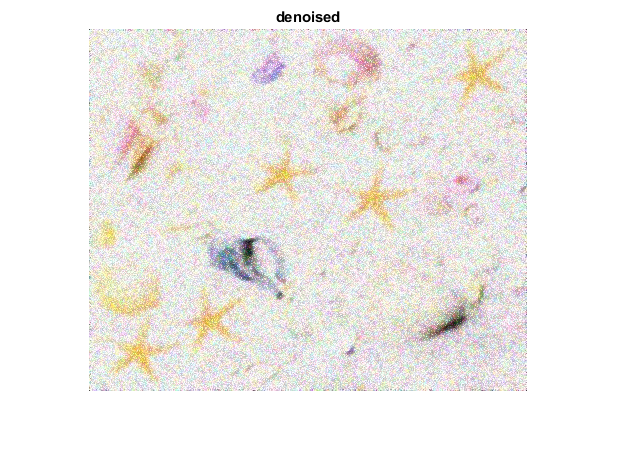


% % Denoise channels
[c1,c2,c3] = imsplit(oim);
c1(n1) = f1(n1);
c2(n2) = f2(n2);
c3(n3) = f3(n3);
denoised = cat(3, c1,c2,c3);
imshow(denoised);
title("denoised");

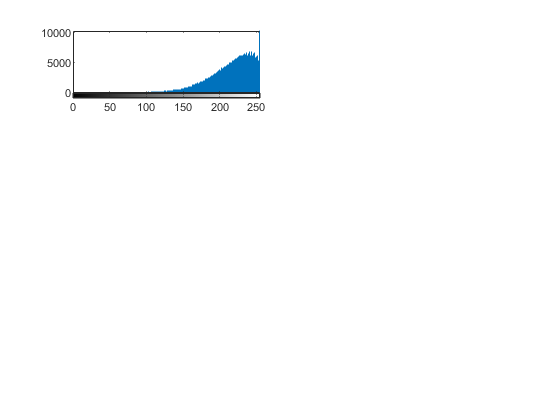

% % % % 

figure

subplot(r,c, (n + 1));
imshow(im);
subplot(r,c, (n + 1));
imhist(im);

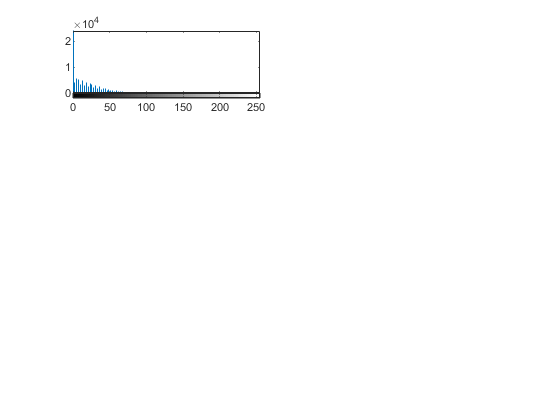


subplot(r,c, (n + 1));
imshow(n1b);
subplot(r,c, (n + 1));
imhist(n1b,100);

myhist = imhist(n1b,100);
histAvgGradient = median(myhist)

histAvgGradient = 4

if (histAvgGradient < 5)
    disp("Gaussian/grain")
elseif (histAvgGradient  < 150)
    disp("salt and pepper")
else
    disp("speckle/mixed")
end

Gaussian/grain


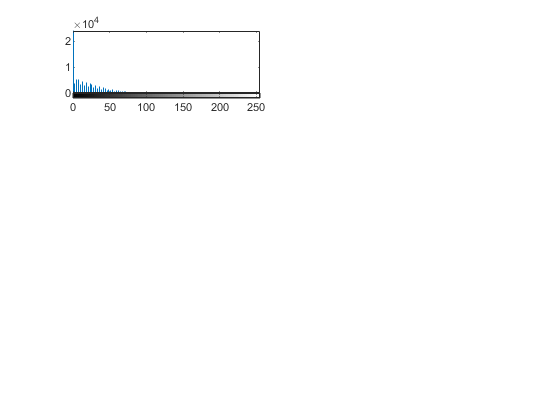


subplot(r,c, (n + 1));
imshow(n2b);
subplot(r,c, (n + 1));
imhist(n2b,100);

myhist = imhist(n2b,100);
histAvgGradient = median(myhist)

histAvgGradient = 9

if (histAvgGradient < 5)
    disp("Gaussian/grain")
elseif (histAvgGradient  < 150)
    disp("salt and pepper")
else
    disp("speckle/mixed")
end

salt and pepper


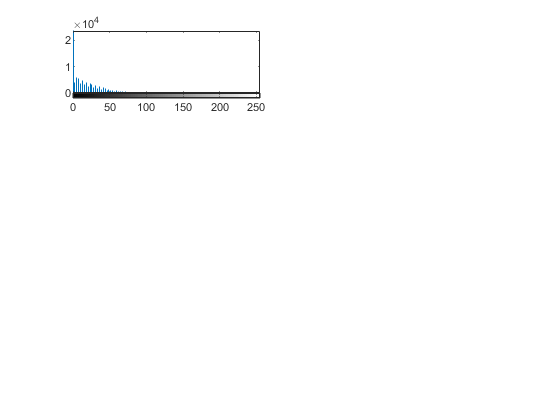


subplot(r,c, (n + 1));
imshow(n3b);
subplot(r,c, (n + 1));
imhist(n3b,100);

myhist = imhist(n3b,100);
histAvgGradient = median(myhist)

histAvgGradient = 4.5000

if (histAvgGradient < 5)
    disp("Gaussian/grain")
elseif (histAvgGradient  < 150)
    disp("salt and pepper")
else
    disp("speckle/mixed")
end

Gaussian/grain
